%% SISTEMA DE CONTROL AVANZADO MYCOBOT
% Integra: ROS 2 (Hardware) + URDF (Modelo) + Planificación Continua

%% 1. Inicialización del Sistema
clear; clc;


% A) Conectar Hardware
try
    robot_hw = erobotics_interface();
    pause(1); % Dar tiempo a recibir el primer mensaje de /joint_states
catch
    warning('ROS 2 no detectado. Modo SIMULACIÓN.');
    robot_hw = [];
end

--- Iniciando Hardware MyCobot ---
 [tf_monitor] Listo para visualizar.
 ¡CONEXIÓN ESTABLECIDA con el Robot!



% B) Cargar Modelo
robot_model = MyCobotModel(); 

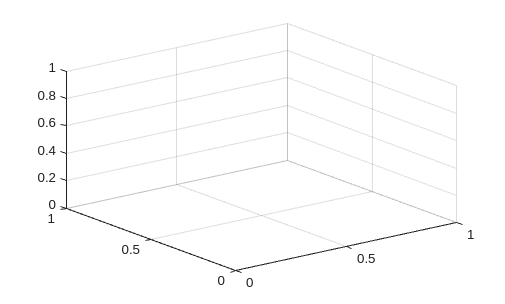


% C) Iniciar Planificador
planner = TrajectoryPlanner(robot_model);


% D) Visualización Inicial (Estado Real)
if ~isempty(robot_hw)
    disp('Sincronizando con el robot real...');
    planner.sincronizarConHardware();
end

disp('Sistema listo.');

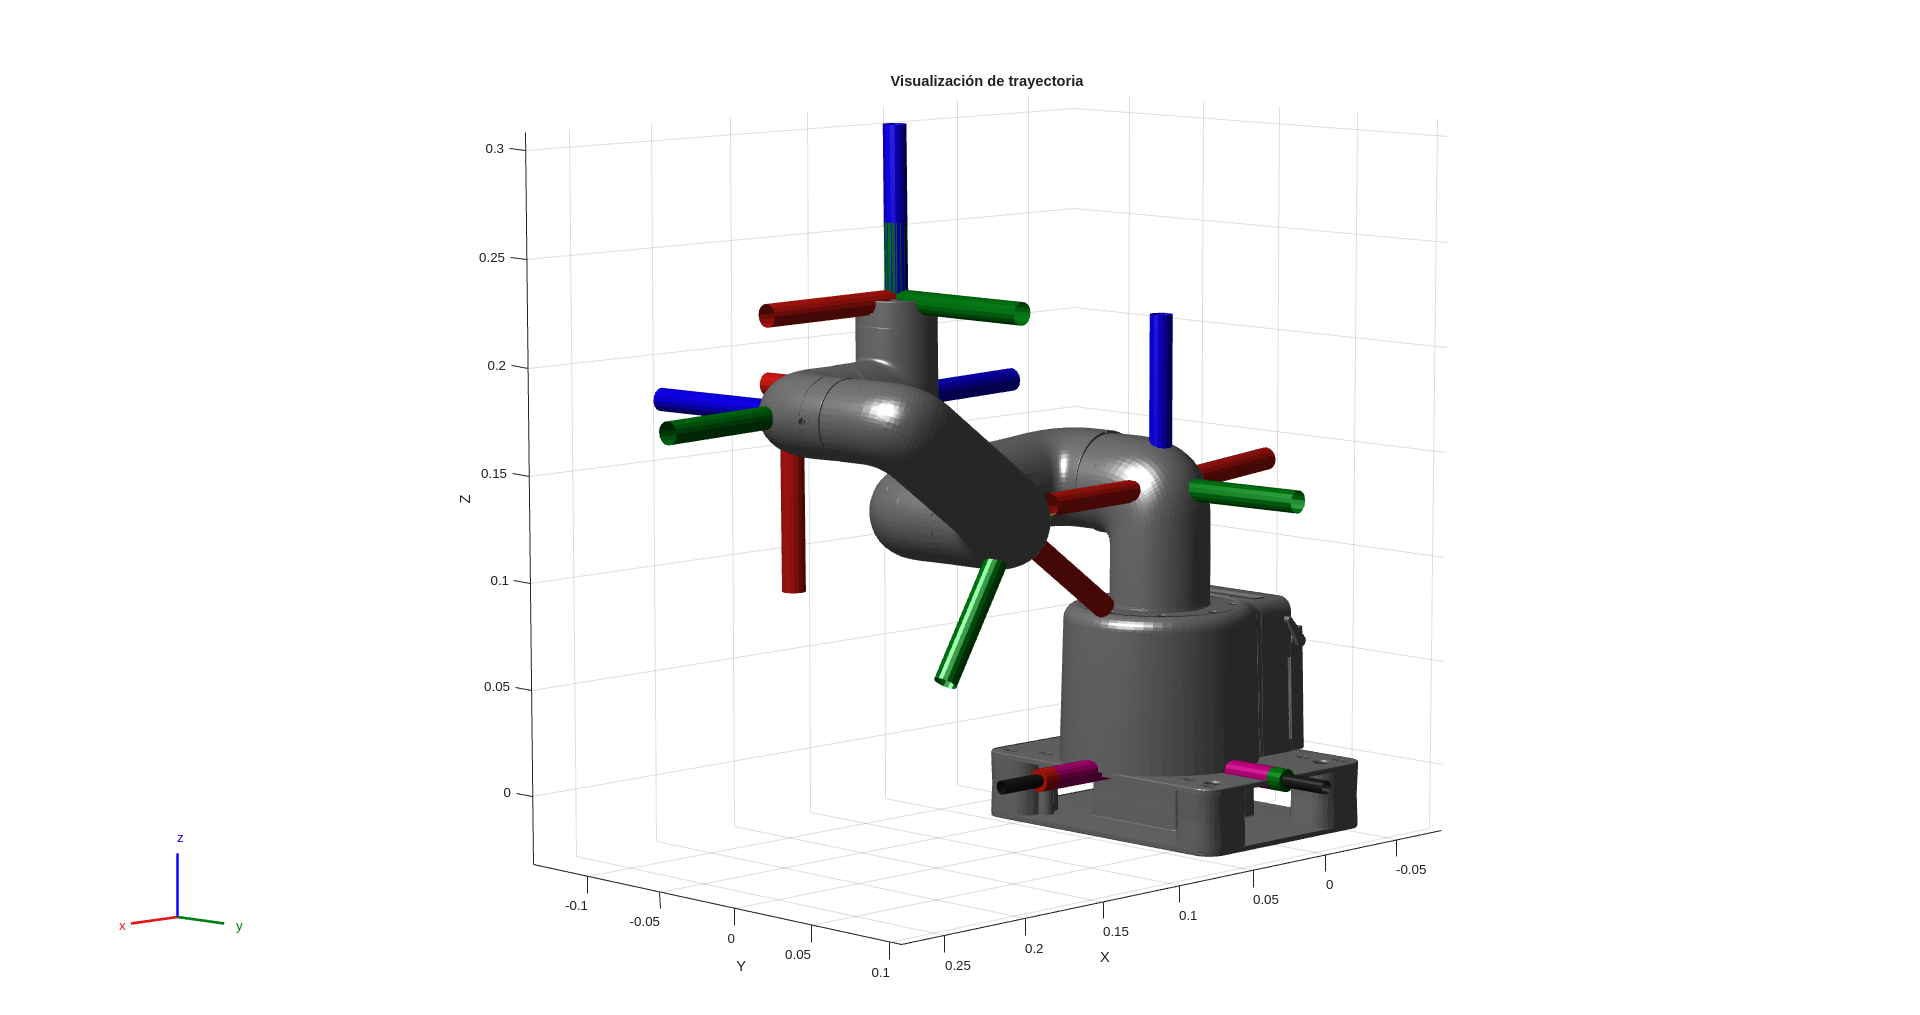

qMatrix =     0.0030    0.0030    0.0014    0.0045         0    0.7807
   -0.2453   -0.6898    0.9110   -0.0378    0.3063    0.8995
   -0.2572   -1.0164    1.1037    0.2804    0.3547    1.0314
   -0.2502   -1.2293    1.0519    0.7327    0.3620    1.1632
   -0.2367   -1.3014    0.7641    1.2782    0.3421    1.2884
   -0.2045   -1.1047    0.0000    2.0215    0.2910    1.3895
   -0.1255   -1.2209    0.0000    2.2971    0.2057    1.4331
   -0.0607   -1.3197    0.0264    2.5307    0.1305    1.4705
    0.0098   -1.5054    0.3725    2.5307    0.0592    1.4867
    0.0801   -1.6301    0.6607    2.5307   -0.0024    1.4907



%% 2. Control Cartesiano (Desde posición actual)
% El robot partirá de donde esté ahora mismo (leído por sensores)
% hacia la nueva coordenada.

x = 0.22; 
y = -0.10; 
z = 0.22;

% Orientación (Radianes)
roll = 0; pitch = 0; yaw = 0;

tiempo = 4.0; 

qMatrix = planner.planificarCartesiano(x, y, z, roll, pitch, yaw, tiempo)

robot_hw.irAHome();

 Enviando trayectoria... Destino: [0.0  0.0  0.0  0.0  0.0 45.0]
